clear;
N=10^4;
x=randn(1,N);
threshold=0.3;
M=100;
n=1:M;

Under_treshold=nnz(x(n)<threshold); 
txt_UT="Samples under threshold: " + num2str(Under_treshold);
Over_treshold=nnz(x(n)>threshold); 
txt_OT="Samples over threshold: " + num2str(Over_treshold);

Theoretical_Under_treshold=normcdf(threshold); 
txt_TUT="Expected samples under threshold: " + num2str(Theoretical_Under_treshold*length(x(n)));
Theoretical_Over_treshold=normcdf(threshold,'upper'); 
txt_TOT="Expected samples over threshold: " + num2str(Theoretical_Over_treshold*length(x(n)));

mu=0; sigma=1;
true_pdf=makedist('Normal',mu,sqrt(sigma));
true_pdf_x = linspace(min(x), max(x), N); % Definer x-verdier for den teoretiske pdf-en
true_pdf_y = pdf(true_pdf, true_pdf_x); % Beregn y-verdier for den teoretiske pdf-en

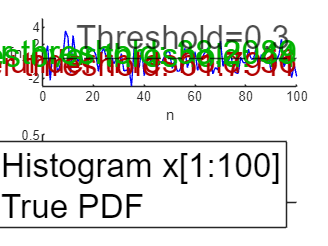

figure;
subplot(2,1,1);
hold on;
plot(n,x(n),'Color', [0 0 1]);
yline(threshold,'--',['Threshold=', num2str(threshold)],'Color', 'k','FontSize',20);
text(M,threshold-0.2,txt_UT,'HorizontalAlignment','right','Color', [0.7 0 0],'FontSize',20);
text(M,threshold+0.6,txt_OT,'HorizontalAlignment','right','Color', [0 0.7 0],'FontSize',20);
text(M,threshold-0.5,txt_TUT,'HorizontalAlignment','right','Color', [0.7 0 0],'FontSize',20);
text(M,threshold+0.9,txt_TOT,'HorizontalAlignment','right','Color', [0 0.7 0],'FontSize',20);
ylabel("x[n]");
xlabel("n");
set(get(gca,'ylabel'),'rotation',0);
subplot(2,1,2);
hold on;
histogram(x,'Normalization','pdf','FaceColor', [0 0 1]);
plot(true_pdf_x, true_pdf_y, '--','Color', [0.7 0 0],'LineWidth',1);
legend("Histogram x[1:"+num2str(M)+"]","True PDF",'FontSize',20);

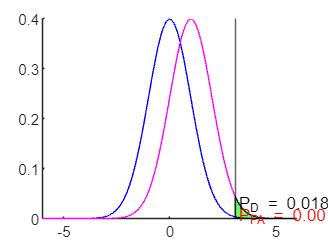

%Oppgave 2
lim=-6:1/400:6;
p1=normpdf(lim, 0, 1); % H0
p2=normpdf(lim, 1, 1); % H1

lamda=exp(qfuncinv(10^-3) - 0.5);
x0=log(lamda) + 0.5;
Pfa=qfunc(log(lamda) + 0.5);
Pd=qfunc(qfuncinv(10^-3) - 1);

figure;
hold on;
plot(lim, p1, 'b'); % Plot p1 in blue
plot(lim, p2, 'm'); % Plot p2 in magenta
xline(x0);

% Find indices corresponding to x0
idx_x0 = find(lim >= x0, 1);


% Fill area under p2 (H1) curve with green
fill([lim(idx_x0:end), lim(end), lim(end), lim(idx_x0)], ...
     [p2(idx_x0:end), 0, 0, p2(end)], 'g', 'FaceAlpha', 0.6);

% Fill area under p1 (H0) curve with red
fill([lim(idx_x0:end), lim(end), lim(end), lim(idx_x0)], ...
     [p1(idx_x0:end), 0, 0, p1(end)], 'r', 'FaceAlpha', 1);

% Add labels
text(x0 + 0.1, max(p1(idx_x0:end)) * 0.9, sprintf('P_{FA} = %.4f', Pfa), 'Color', 'r');
text(x0 + 0.1, max(p2(idx_x0:end)) * 0.6, sprintf('P_{D} = %.4f', Pd));

hold off;